clear 
RGB = orderedcolors('glow12')

RGB =     0.1490    0.5490    0.8660
    0.9600    0.4660    0.1600
    1.0000    0.9090    0.3920
    0.7520    0.3600    0.9840
    0.2860    0.8580    0.2500
    0.4230    0.9560    1.0000
    0.9490    0.4030    0.7720
    1.0000    0.4780    0.4540
    0.4900    0.6620    1.0000
    0.9960    0.7520    0.2980


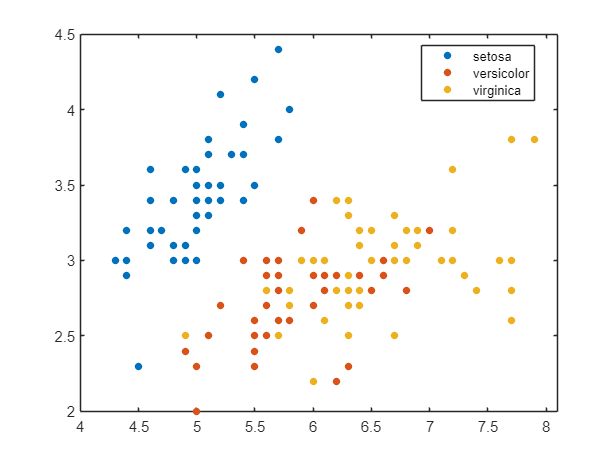

load fisheriris
X = meas;
Y = species; Y = string(Y);
gscatter(X(:,1),X(:,2),Y)

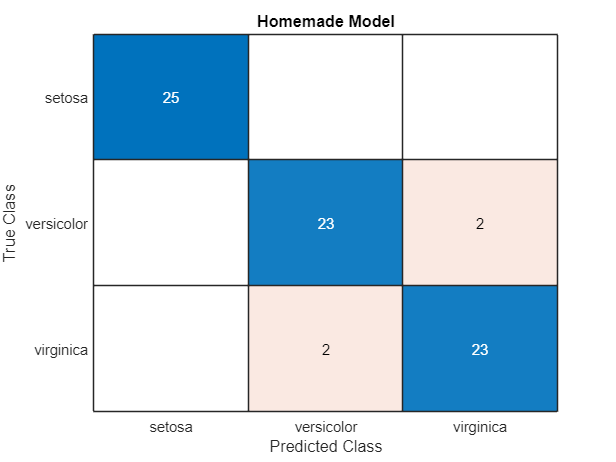


cv = cvpartition(Y,'Holdout',0.5);
X_training = X(cv.training,:); Y_training = Y(cv.training,:);
X_test = X(cv.test,:);

fileDirectory = fullfile('D:/Proton Drive/Lasseb200/My files/Master/MachineLearning');
addpath(fullfile(fileDirectory,'NB'));
Y_pred = NB(X_training,Y_training,X_test);

Y_test = Y(cv.test);
confusionchart(Y_test,Y_pred)
title('Homemade Model')